# ILLUSTRAZIONE GRAFICA DEL PUNTO DI BREAK EVEN

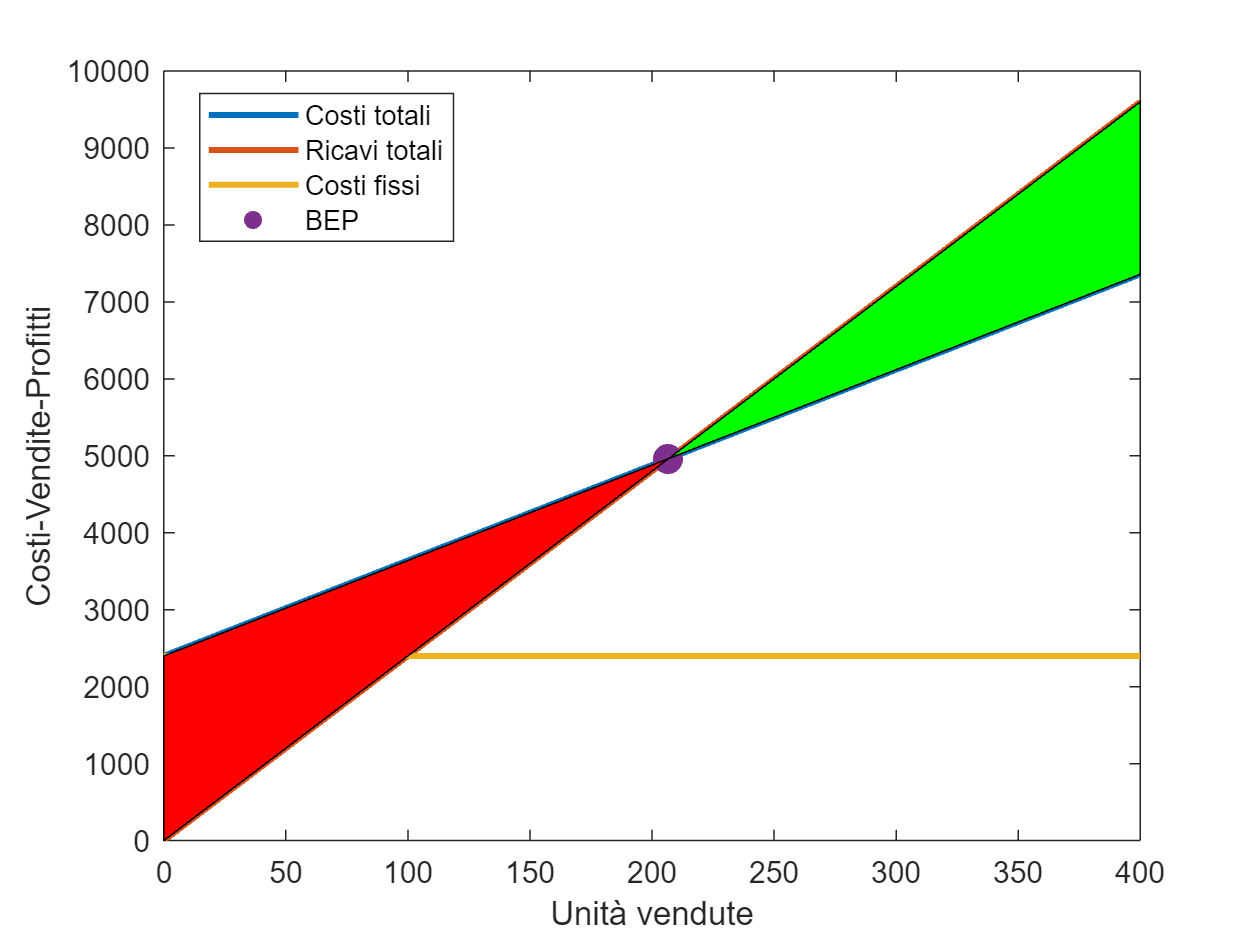

costovariabile=4.5;
% prezzo unitario
prezzounitario=26;
costofisso=2400;
regioniColore=true;
aggiungicoord=false
%unitVendute = unità vendute
unitVendute=(0:100:400)';

lwd=2;

% CF = Costi fissi
CF=costofisso*ones(length(unitVendute),1);
% CT = Costi totali = Costi fissi + costi variabili
CT=CF+costovariabile*unitVendute;
% RT = ricavo totale = unità vendute * prezzo unitario
RT=unitVendute*prezzounitario;

X=[CT RT CF];
close all
hold('off')
plot(unitVendute,X,'LineWidth',lwd)
xlabel('Unità vendute')
ylabel('Costi-Vendite-Profitti')

% Per trovare l'intersezione mi serve una granularità maggiore
unitVendute1=(0:0.01:400)';
CT1=costofisso+costovariabile*unitVendute1;
RT1=unitVendute1*prezzounitario;
% pos trova la posizione in cui la differenza tra Costo totale e Ricavo
% totale è inferiore ad una certa soglia (ad esempio minore di 1)
pos=find(abs(CT1-RT1)<1);
% Nel caso in cui find trovi più intersezioni prendiamo la prima
if isempty(pos)
    disp('Attenzione il punto di intersezione non è stato trovato')
    disp('nell''intervallo specificato di unità vendute')
    disp('E necessario aumentare il prezzo unitario o diminuire il costo fisso o quello variabile')
    suv=">400";
    hold('on')
    scatter(NaN,NaN)
else
    pos=pos(1);
    unitVenduteBkeakEven=unitVendute1(pos);
    % Osservazione: in corrispondenza di unitVenduteBkeakEven
    % CT1(pos)=RT1(pos)
    ybreakeven=CT1(pos);
    hold('on')
    % Aggiungo il punto di break even

    scatter(unitVenduteBkeakEven,ybreakeven,100,'filled')

    suv=string(unitVenduteBkeakEven);
    if regioniColore ==true
        % Riempi la regione relativa all'utile
        fill([unitVenduteBkeakEven;400;400],[ybreakeven;CT1(end);RT(end)],'g')
        % Riempi la regione relativa alla perdita
        fill([0;unitVenduteBkeakEven;0],[0;ybreakeven;CT1(1)],'r')
    end

    if aggiungicoord==true
        line([unitVenduteBkeakEven;unitVenduteBkeakEven],[0;ybreakeven],'LineStyle','--')
        line([0;unitVenduteBkeakEven],[ybreakeven;ybreakeven],'LineStyle','--')
    end
end
legend(["Costi totali" "Ricavi totali" "Costi fissi" "BEP" ],'Location','best');

disp('-----------------------')

-----------------------


disp("Unità da vendere per Break even="+suv)

Unità da vendere per Break even=206.82


disp('----------------------')

----------------------
